# SSBurstEx.mlx

generates an SS burst, demonstrating the different possible parameter values, including block pattern cases and periodicity values.  Both the corresponding resource grid and time-domain waveform are displayed.

## Configure an example carrier

carrier = nrCarrierConfig;
carrier.SubcarrierSpacing = 15;
carrier.CyclicPrefix = 'Normal';
carrier.NSizeGrid = 52;
carrier.NCellID = 42;
carrier.NSlot = 0;
waveformInfo = nrOFDMInfo(carrier);

## Create a SS burst information structure with SS burst configuration parameters

ssburst = struct;

## Configure parameters related to SS burst / blocks:

ssburst.BlockPattern = 'Case B';            % 30kHz subcarrier spacing
ssburst.NCellID = carrier.NCellID;

nSubframe = carrier.NSlot / carrier.SlotsPerSubframe;
ssburst.NFrame = floor(nSubframe / 10);
ssburst.NHalfFrame = mod(nSubframe / 5,2);

ssburst.SSBTransmitted = [1 1 1 1 1 1 1 1]; % Bitmap indicating blocks transmitted in the burst
ssburst.SSBPeriodicity = 10;                % SS burst set periodicity in ms (5, 10, 20, 40, 80, 160)
ssburst.FrequencySSB = 0;

## Configure parameters related to SIB1, PDCCH, and PDSCH:

ssburst.SampleRate = waveformInfo.SampleRate;
ssburst.DMRSTypeAPosition = 2;
ssburst.SubcarrierSpacingCommon = 15;
ssburst.PDCCHConfigSIB1 = 0;

## Configure other parameters related solely to MIB content:

ssburst.CellBarred = 0;
ssburst.IntraFreqReselection = 0;

## Enable resource grid display for SS Burst

ssburst.DisplayBurst = true;        % display resource grid for SS Burs

## Generate SS burst, compute waveform, and show visualizations

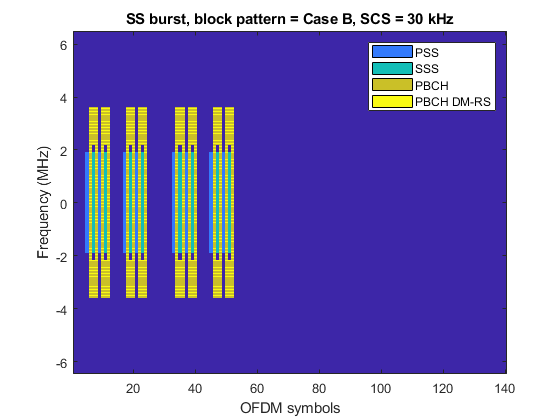

[ssbWaveform,ssbGrid,ssbInfo] = hSSBurst(ssburst);

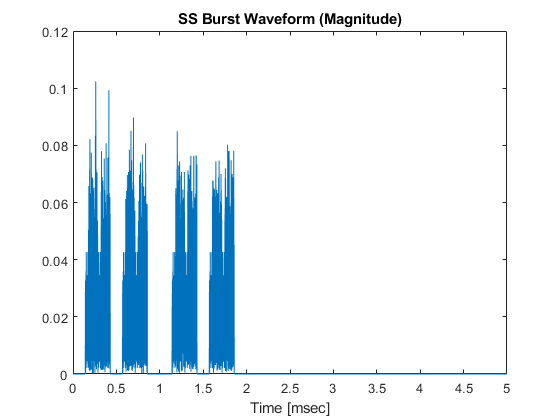


figure(100)
t = (0:length(ssbWaveform)-1)/ssbInfo.SampleRate*1000;
plot(t,abs(ssbWaveform))
xlabel('Time [msec]')
title('SS Burst Waveform (Magnitude)')